%This code reproduces Extended Fig1 from the second rebuttal submitted to Nature2020
%paper (Nienhuis et al., 2020). It needs v1 dataset provided by Jaap Nienhuis

v1 = load ('V1\GlobalDeltaData_v1.mat');%provided by Jaap Nienhuis
%v11 = load ('V1.1\GlobalDeltaData.mat');
v2 = load ('V2\GlobalDeltaData.mat') %from https://github.com/jhnienhuis/GlobalDeltaChange
v2.ee = load('V2\land_area_change\GlobalDeltaData_AreaChange.mat');
load 'V1/BasinID2';
BasinID2 = double(BasinID2);

v2 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
           BasinID2: [10848×1 int64]
      BasinID_ATLAS: [10848×1 int64]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
                 Hs: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
              QWave: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
      RiverID_ATLAS: [1×10848 int64]
           TidalAmp: [10848×1 double]
                 Tp: [10848×1 double]
        channel_len: [10848×30 double]
    channel_len_lat: [10848×30 double]
    channel_len_lon: [10848×30 double]
      channel_slope: [10848×1 double]
         delta_name: [10848×1 s


random108 = readtable('EE_108randomdeltas_ordered.csv'); % from https://github.com/FlorinZai/Global_Delta_Check
Max_deltas100 = readtable('EE_Max100Big_polys_change.csv');

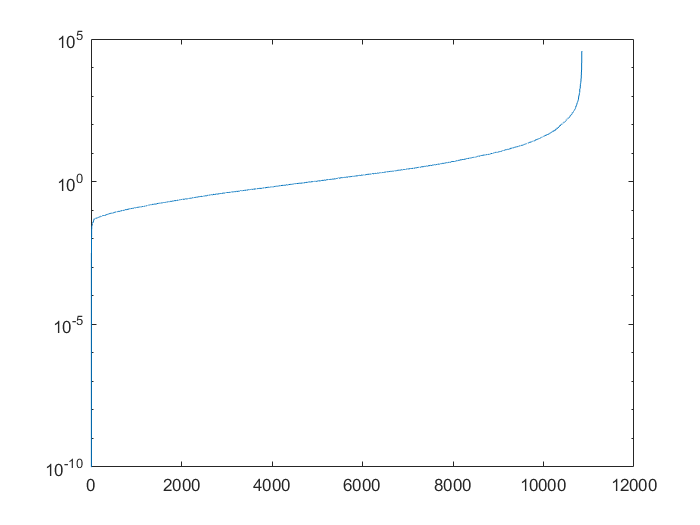

SortQ = sort(v1.QRiver_prist);
plot(SortQ)
set(gca, 'YScale', 'log')


% SortQs = sort(Discharge_prist);
% plot(SortQs)
% set(gca, 'YScale', 'log')
% 
% S_perc = prctile(QRiver_prist, 80)
% Q_perc = prctile(Discharge_prist, 80)


Qsort = [v1.QRiver_prist v1.BasinID BasinID2 v1.MouthLon v1.MouthLat];
Qsort = sortrows(Qsort);
[~,idrandom108] = ismember(random108.BasinID, Qsort(:,2)); 
[~,DeltaID_Max100_sort] = ismember(Max_deltas100.ID, Qsort(:,3));

Qsorted = Qsort(:,1);

plot(Qsorted)
set(gca, 'YScale', 'log')


%How much q prist

NoMax100 = (zeros(1, 10848)+1)';
NoMax100(DeltaID_Max100_orig) = 0;
NoMax100= logical(NoMax100);
Max100 = ~NoMax100;%logical max 100

TotalSedMax100 = sum(v1.QRiver_prist(Max100))

TotalSedMax100 = 3.4083e+05

TotalSed = sum(v1.QRiver_prist)

TotalSed = 4.8538e+05

PercentageSed = TotalSedMax100/TotalSed *100

PercentageSed = 70.2202

%sum(Qsort(10828:10848,1))
%sum(Qsort(1:10828,1))
%sum(Qsort(10748:10848,1))

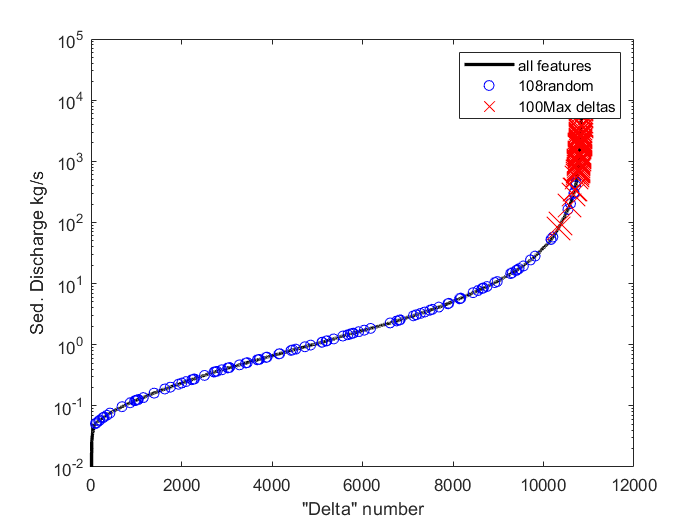

clf
plot(Qsort(:,1),'k','LineWidth',2)
set(gca, 'YScale', 'log')
ylim ([0.01 100000])
hold on
plot(idrandom108, Qsorted(idrandom108), 'o', 'MarkerSize', 6,'Color','blue')
plot(DeltaID_Max100, Qsorted(DeltaID_Max100_sort), 'x', 'MarkerSize', 20,'Color','red')
hold off
xlabel ('"Delta" number')
ylabel ('Sed. Discharge kg/s')
legend ('all features','108random', '100Max deltas')

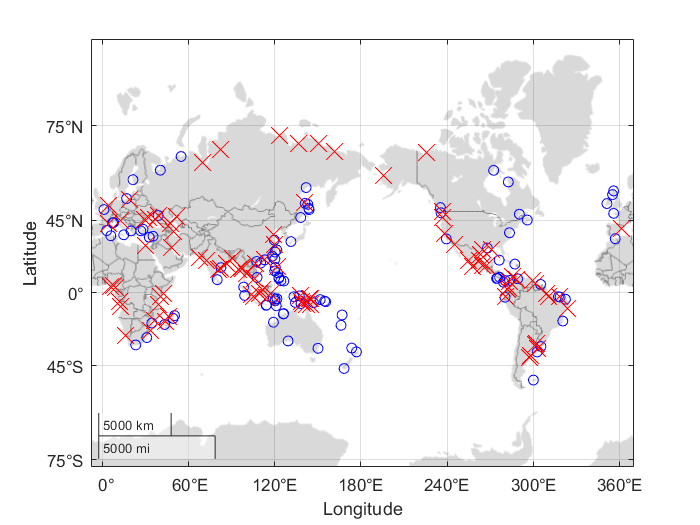

clf
geoscatter(Qsort(idrandom108,5),Qsort(idrandom108,4),'blue')	
hold on
geoscatter(Qsort(DeltaID_Max100,5),Qsort(DeltaID_Max100_sort,4),200,'x','r')
geobasemap 'grayland'
hold off